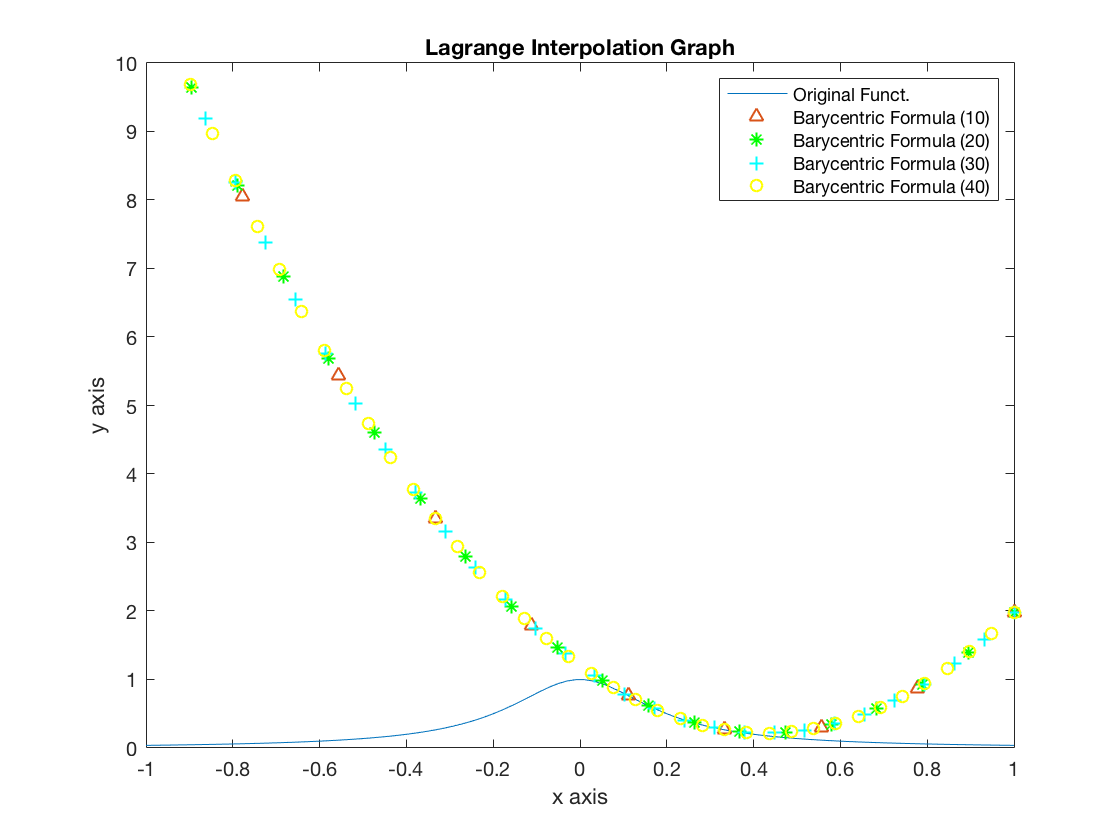

% Number 1A
% Yes, increasing the number of sample points gives a better
% approximation because it makes the exact function less choppy.
% Consulted with Jhon for ideas on how to approach the problem
f = @(x) (1./(1+25*x.^2));

X = linspace(-1,1,100);
x1 = linspace(-1,1,10);
x2 = linspace(-1,1,20);
x3 = linspace(-1,1,30);
x4 = linspace(-1,1,40);

y1 = linterp_bary([.1 .2 .3],f,x1);
y2 = linterp_bary([.1 .2 .3],f,x2);
y3 = linterp_bary([.1 .2 .3],f,x3);
y4 = linterp_bary([.1 .2 .3],f,x4);

%Graph Making
plot(X,f(X),'-',x1,y1,'^',x2,y2,'g*',x3,y3,'c+',x4,y4,'yo');
ylim([0,10]);
title('Lagrange Interpolation Graph')
legend('Original Funct.','Barycentric Formula (10)','Barycentric Formula (20)','Barycentric Formula (30)','Barycentric Formula (40)','Location','northeast')
xlabel('x axis');
ylabel('y axis');

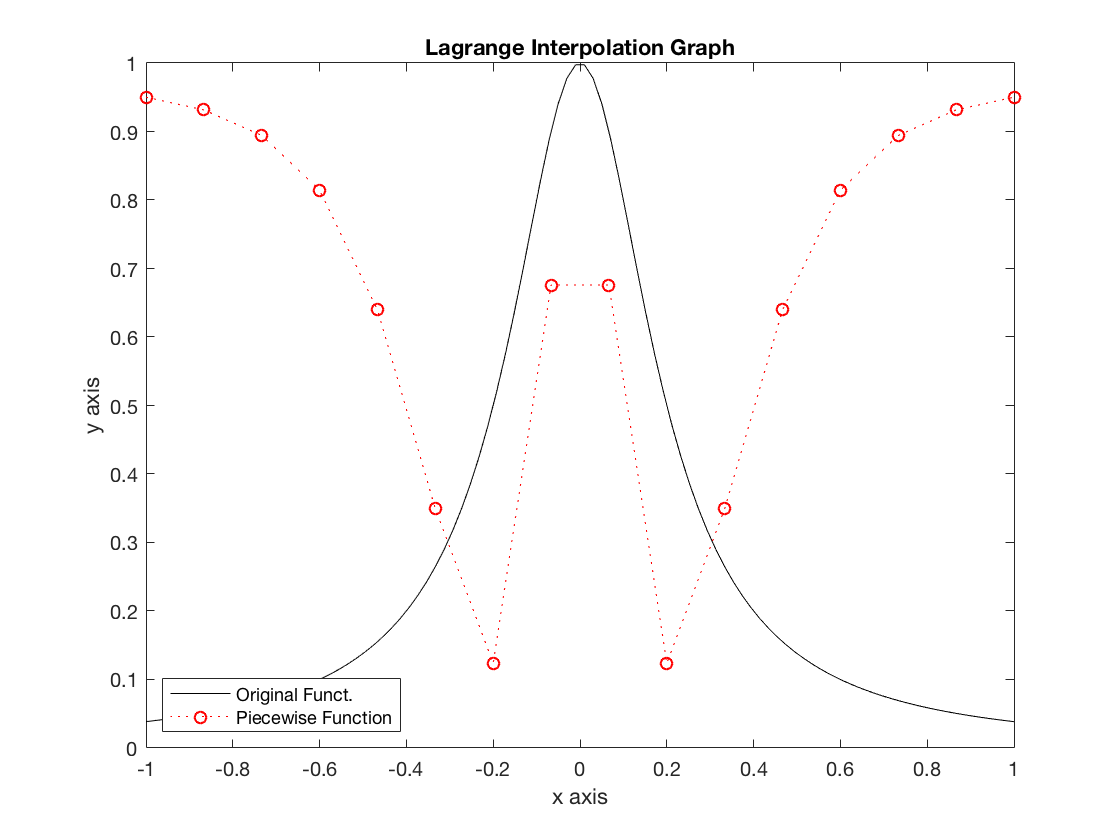

% Number 1B
% The approximation is not better than those from part (a),
% it looks more choppier.
x_sample = linspace(-1,1,16);
y_sample = f(x_sample);
xone = linspace(-1,1,16);

y = linterp_bary(x_sample,f,y_sample);
plot(X,f(X),'k-',xone,y,'ro:');
title('Lagrange Interpolation Graph')
legend('Original Funct.','Piecewise Function','Location','southwest');
xlabel('x axis')
ylabel('y axis')

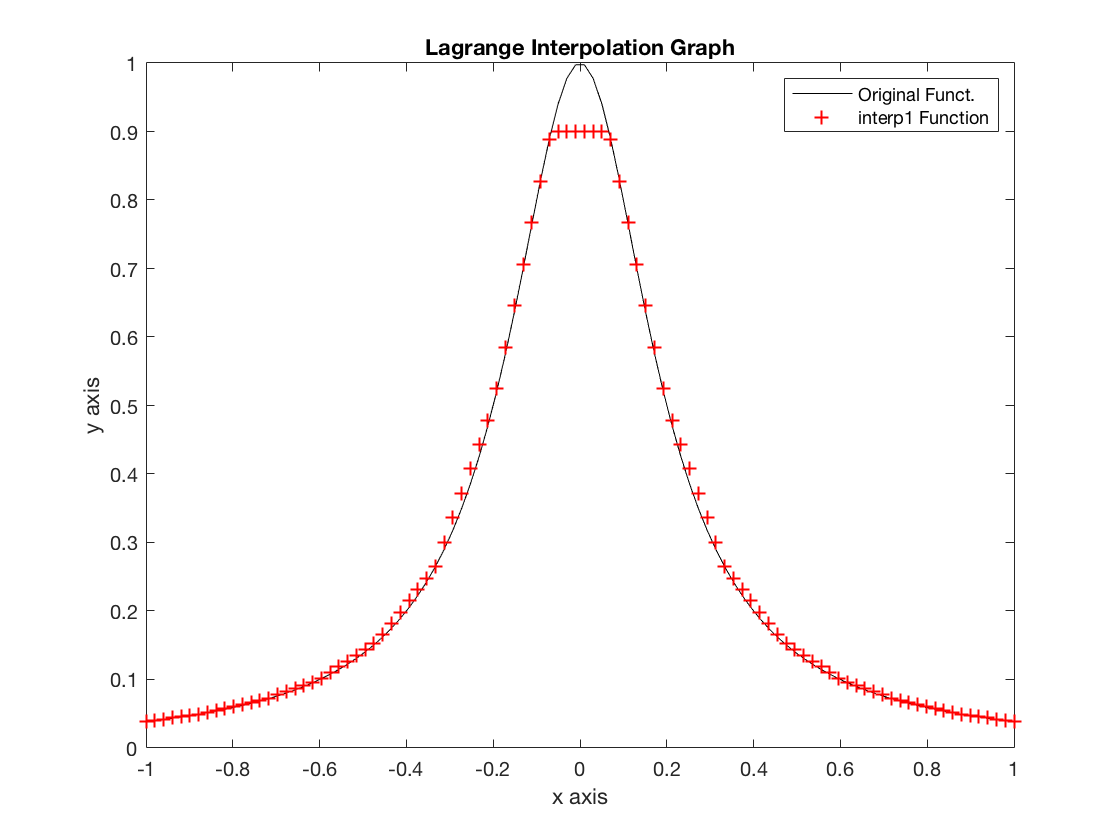

%Problem 1C
y = interp1(x_sample,y_sample,X);

plot(X,f(X),'k-',X,y,'r+');
title('Lagrange Interpolation Graph')
legend('Original Funct.','interp1 Function','Location','northeast')
xlabel('x axis')
ylabel('y axis')

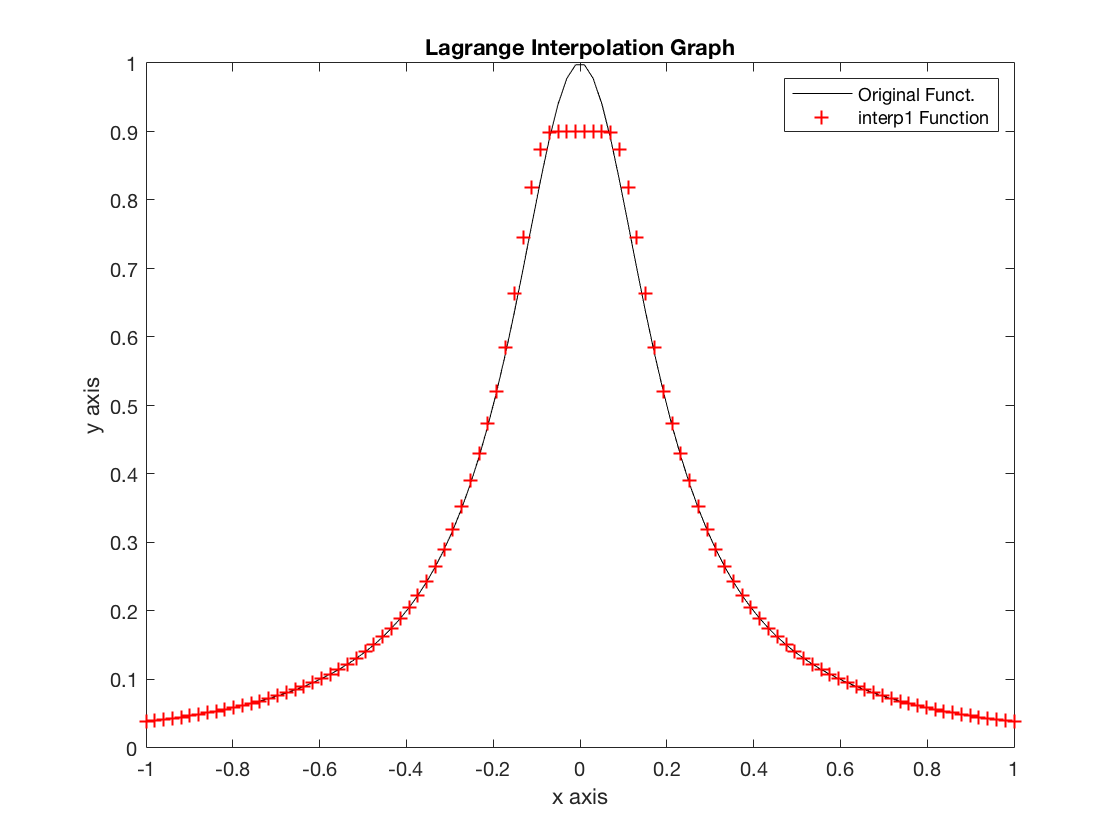

% Problem 1D
% These approximations look similar to part c but not close to b.
% Also it looks a little less accurate than part C.
y = pchip(x_sample,y_sample,X);

plot(X,f(X),'k-',X,y,'r+');
title('Hermite Interpolation Graph')
legend('Original Funct.','interp1 Function','Location','northeast')
xlabel('x axis')
ylabel('y axis')

function y = linterp_bary(X, Y, x)
% The function linterp_bary is the same as lagrange except better because
% it uses the barycentric weights instead of interpolation of arrays
% X = An array of real numbers that describe the formula.
% Y = An array of the evaluation of the polynomial.
% x = An array of real numbers besides the ones in X.

n = length(x);
y_arr = ones(1,n);

for h = 1:n
    n = length(X);
    w = ones(1,n);
    for i = 1:n
        for j = 1:n
            if i~=j
                w(i) = w(i) * (X(i)-X(j));
            end
        end
    end
w = 1./w;
yy = w ./(x(h)-X);

y_num = (yy .* Y(X));

yyy = sum(y_num);
y_arr(h) = yyy/sum(yy);
end
y = y_arr;
end